clc;clear;close;
commodity = "AUDUSD";
dataTable = readtable('AUDUSD60.csv','Format','%{yyyy.MM.dd HH:mm}D %f%f%f%f%d');
Data = table2timetable(dataTable);

inputWindowSize =240;
slidingWindowSize = 24;

load(commodity+'_CNN_net.mat', 'net');
% Preparing Environment
if isfolder(commodity+"Test")
    rmdir(commodity+"Test", 's');
end
mkdir(commodity+"Test");
mkdir(commodity + "Test/Buy");
mkdir(commodity + "Test/Hold");
mkdir(commodity + "Test/Sell");

%indices = randperm(size(dataTable, 1) - inputWindowSize, 100);
indices = 1:size(dataTable, 1) - inputWindowSize;

% Calculate Signals
signalLookBackPeriod = 14;
atr = indicators([dataTable.High,dataTable.Low,dataTable.Close] ,'atr' ,signalLookBackPeriod);
%atr = BAR_indicator([dataTable.High,dataTable.Low],10 ,3);
highs = dataTable.High + atr;
lows = dataTable.Low - atr;
highestHighs = zeros(size(dataTable,1) - slidingWindowSize, 1);
lowestLows = zeros(size(dataTable,1) - slidingWindowSize, 1);
signals = zeros(size(dataTable,1) - slidingWindowSize, 1);

for index = signalLookBackPeriod : size(dataTable,1) - slidingWindowSize
    highestHighs(index) = max(dataTable.High(index:index+slidingWindowSize));
    lowestLows(index) = min(dataTable.Low(index:index+slidingWindowSize));
    if highestHighs(index) >= highs(index) && lowestLows(index) >= lows(index)
        signals(index) = 1;
    elseif lowestLows(index) <= lows(index) && highestHighs(index) <= highs(index)
         signals(index) = -1;
    end
end

% Calulate Indicators to show on chart
ma1 = indicators(dataTable.Close ,'sma' , 8);
ma2 = indicators(dataTable.Close ,'sma' , 24);
ma3 = indicators(dataTable.Close ,'sma' , 120);
rsi = indicators(dataTable.Close, 'rsi');
macd = indicators(dataTable.Close, 'macd', 12, 26, 9);
boll = indicators(dataTable.Close, 'boll');

% Draw & Export Charts
counter = 0;
for ii = indices
    counter = counter + 1
    t = tiledlayout(10,1);
    mainT = tiledlayout(t, 1,1);
    mainT.Layout.Tile = 1;
    mainT.Layout.TileSpan=[8,1];
    ax1= nexttile(mainT);
    hold on;
    % add indocators
    plot(ma1(ii:ii + inputWindowSize), 'Blue');
    plot(ma2(ii:ii + inputWindowSize), 'Green');
    plot(ma3(ii:ii + inputWindowSize), 'Red');
    plot(boll(ii:ii + inputWindowSize,1), "Yellow");
    plot(boll(ii:ii + inputWindowSize,2), "Cyan");
    plot(boll(ii:ii + inputWindowSize,3), "Magenta");
    candlestick_plot(Data(ii:ii + inputWindowSize,:), 1:inputWindowSize + 1, 'DownColor', 'Black', 'UpColor', 'White')
    ax2= nexttile(t);
    plot(macd(ii:ii + inputWindowSize, 1), 'Blue');
    hold on;
    plot(macd(ii:ii + inputWindowSize, 2), 'Green');
    plot(macd(ii:ii + inputWindowSize, 3), 'Red');
    ax3= nexttile(t);
    plot(rsi(ii:ii + inputWindowSize), "Yellow");
    linkaxes([ax1,ax2,ax3],'x');
    xticklabels(ax1,{});
    xticklabels(ax2,{});
    t.TileSpacing = 'none';
    
    x0=10;
    y0=10;
    width=1280;
    height=768;
    set(gcf,'position',[x0,y0,width,height]);
    %exportgraphics(gca, "image" + counter + ".png");
    saveas(gca, "image" + counter + ".png");
    if (signals(ii+1+ inputWindowSize) == 1)
        movefile("image" + counter + ".png", commodity+"Test/Buy");
    elseif (signals(ii+1+ inputWindowSize) == -1)
        movefile("image" + counter + ".png", commodity+"Test/Sell");
    else
        movefile("image" + counter + ".png", commodity+"Test/Hold");
    end
    close;
end


ds = imageDatastore(commodity+"Test","IncludeSubfolders",true, "LabelSource","foldernames", "ReadFcn", @customreader);
augmented = augmentedImageDatastore([1200 2000 3], ds);
labelpredictions = classify(net, augmented);
accuracy = sum(labelpredictions == ds.Labels)/numel(ds.Labels)

accuracy = 0.5581

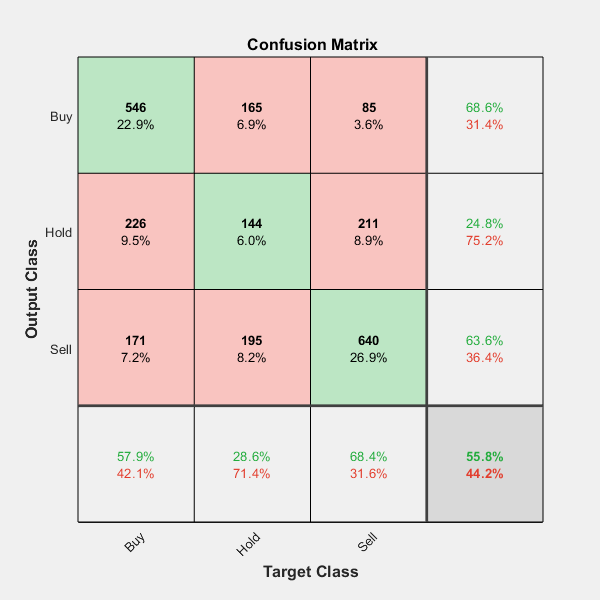

plotconfusion(ds.Labels, labelpredictions);

predictions = predict(net, augmented);
[predictedSignalValues,predictedSignalIndices] = max(predictions,[],2);
output = strings(size(predictedSignalIndices,1), 8);
for ii = 1 : size(predictedSignalIndices,1)
    tp = 0;
    stop = 0;
    filename = split(augmented.Files(ii), '\');
    startPoint = str2double(extractBetween(filename(length(filename)), 'image', '.png'));
    switch predictedSignalIndices(ii)
    case 1
        stop = dataTable.Low(startPoint+inputWindowSize) - atr(startPoint+inputWindowSize);
        tp = dataTable.High(startPoint+inputWindowSize) + atr(startPoint+inputWindowSize);
    case 3
        stop = dataTable.High(startPoint+inputWindowSize) + atr(startPoint+inputWindowSize);
        tp = dataTable.Low(startPoint+inputWindowSize) - atr(startPoint+inputWindowSize);
    end
    output(ii, :) = [string(dataTable.DateTime(startPoint+inputWindowSize)) predictedSignalIndices(ii) predictions(ii,:) atr(startPoint+inputWindowSize) tp stop];
end
writematrix(output, 'predictions.csv');

function data = customreader(filename)
    data = imread(filename);
    data = imresize(data,[1200 2000]);
    %data = rgb2gray(data);
end